##  Applying the TCF3 classifier on your data

- Download all files, including the custom  .m function from GitHub

- Open the MATLAB and place the files in your working directory or add the files to the MATLAB path

- Load the data

To proceed with the code, after adjusting the code to match your data, click on the "Run" button

load("classifier_structure.mat");

        4. Extract the selected genes that were used in the classifier. The genenames are stored in the selected_genes variable in the classifier structure, The '-' in the gene names was replaced with '_', so need to replace it back.

selected_genes = strrep(trainedClassifier_TCF3targets.ClassificationKNN.ExpandedPredictorNames, '_', '-');

        5. Load your data. Here as an example we load the Lenz microarray data (GSE10846), which is stored in the 'celldataLenz_selected' variable. The samples are selected based on threatment (R-CHOP) and age >=18.

mydata = celldataLenz_selected;

        6. Indicate the first row where the expression data starts and the row with sample labels.  E.g., if your data has a header, then data may start at row 2. In our example, the first row consists of sample labels and the data starts at row 2 

rowWhereDataStarts = 2;
rowWithSampleNames = 1;

        7.  Indicate the first columns there the expression data starts and the column with the gene names. E.g. if you have gene names and gene IDs as first 2 columns, then the data will start at column 3. In our example, the gene names are stored in column 2 and the data starts at column 3

colWhereDataStarts = 3;
columnWithGeneNames = 2;

        8. Extract the selected genes in the order they were used in the classifier - indicated by the 'stable' parameter. 

        9. Check the 'notfound' variable, it must be empty. If it is not, then some of the our selected genes (n=23) were not found in your dataset.  Check which genes were not found and see if they have synonimous names.

[~, ~, indB] = intersect(selected_genes, mydata(rowWhereDataStarts:end, columnWithGeneNames), 'stable');
notfound = setdiff(selected_genes, mydata(rowWhereDataStarts:end, columnWithGeneNames));
if length(selected_genes) ~= length(indB)
    disp('Not all genes are found in your dataset')
    return
end

**CRITICAL: don't proceed any further unless you found all the matching genes! and the 'notfound' variable is empty.**

        10. Preprocess your data the same way as the training set. The data must be log2 transformed and minmax standardized across the samples. As a result, each sample will have a 0 for the lowest expressing gene and 1 for the highest expressing gene.

mydata_selected = mydata([1:rowWhereDataStarts-1; indB+rowWhereDataStarts-1], :);
mydata_numeric = cell2mat(mydata_selected(rowWhereDataStarts:end, colWhereDataStarts:end));
mydata_numeric = log2(replaceZeros(mydata_numeric, 'lowval'));
mydata_numeric = minmax_standardize(mydata_numeric, 2);

        11. Visulize the distribution of the selected genes in the Nanostring KGH cohort that was used to develop the classifier. 

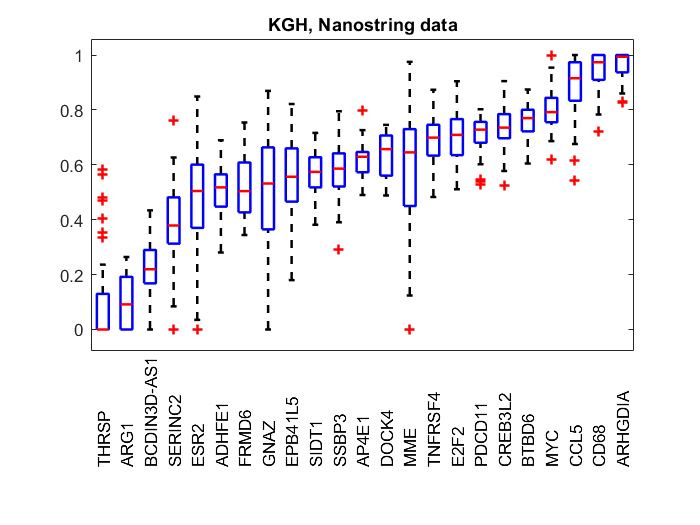

figure;
KGH_numeric = cell2mat(celldata_KGH_selected(2:end, 2:end));
KGH_numeric = log2(replaceZeros(KGH_numeric, 'lowval'));
KGH_numeric = minmax_standardize(KGH_numeric, 2);
sample_labels = celldata_KGH_selected(2:end, 1);
h=boxplot(KGH_numeric', 'labels', sample_labels, 'labelorientation', 'inline');
set(h,{'linew'},{1.5});
title('KGH, Nanostring data');

       12. Visualize the dinstribution of the selected genes in your data and compare it to the distributions in the Nanostring dataset (step 11).  The better the match to our Nanostring data, the more optimal the classification will be. 

       13. Double check that the order of the genes in the two plots matches.

Note, in this example we used a microarray data. Therefore, for some of the genes the range of expression is not matching between the two sets (e.g. 'EPB41L5'). In this case, the classification is possible, but not optimal.

**DO NOT manipulate the data** by adjusting median expression of individual genes!  Instead look into changing your data preprocessing, including alignment,  and normalization methods. If you are using microarray data, try to find alternative probes.

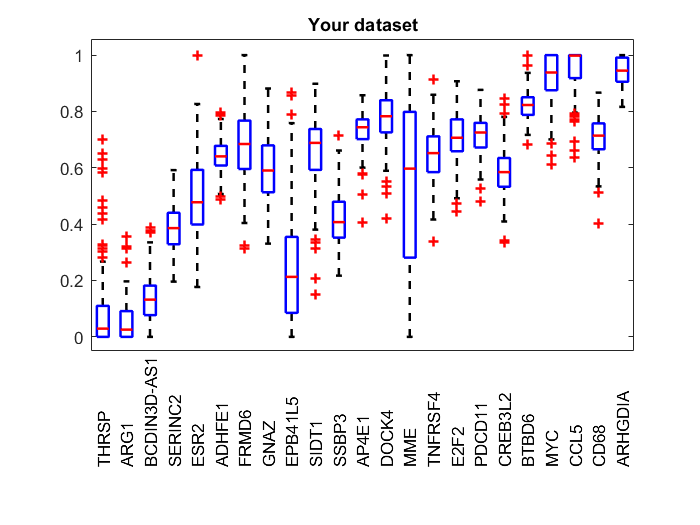

figure;
sample_labels = mydata(rowWhereDataStarts:end, columnWithGeneNames);
h = boxplot(mydata_numeric', 'labels', sample_labels, 'labelorientation', 'inline');
set(h,{'linew'},{1.5}); 
title('Your dataset');

        14. Run the classifier to classify the samples in your dataset into cluster A or B, the results are: 1 = groupA, 0 = groupB.  The classification results are store in the 'subtypeClass' variable. The order of the labels corresponds to the order of samples in your dataset.

subtypeClass = trainedClassifier_TCF3targets.predictFcn(mydata_numeric); 

        15. Plot a heatmap with the classified subtypes as a colour label

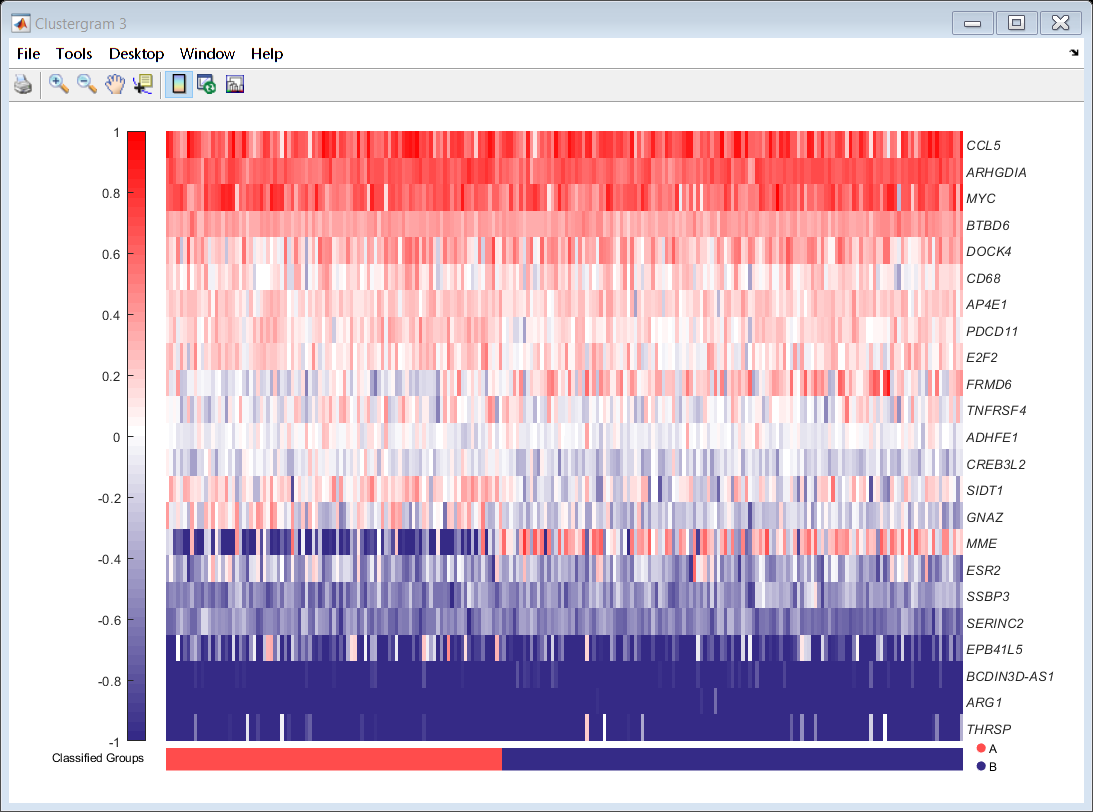


mydata_numeric = cell2mat(mydata_selected(rowWhereDataStarts:end, colWhereDataStarts:end));
mydata_numeric = log2(replaceZeros(mydata_numeric, 'lowval'));
mydata_numeric = mydata_numeric-median(median(mydata_numeric, 2));

%sort by the classification
[subtypeClass_sorted, indA] = sort(subtypeClass,'descend');
mydata_numeric = mydata_numeric(:, indA);
sample_labels = mydata(rowWithSampleNames, indA+colWhereDataStarts-1);
gene_labels = mydata(rowWhereDataStarts:end, columnWithGeneNames);

c = clustergram(mydata_numeric, 'RowLabels',gene_labels,...
    'ColumnLabels',sample_labels, 'RowPDist', 'euclidean',...
    'ColumnPDist', 'Spearman', 'Colormap', 'myColourMap_RedBlue',...
    'DisplayRange', 1,'Cluster', 1, 'ShowDendrogram', 'off');

red = [1, .3, .3];
blue = [.21, .17, .53];

% show classification results under the clustergram
clinical_labels = struct();
groups = cell(size(subtypeClass_sorted));
groups(1:end) = {'B'};
groups(subtypeClass_sorted==1) = {'A'};
clinical_labels.label1.labels = groups;
clinical_labels.label1.colours = [red; blue];
clinical_labels.label1.ordered_lbls = {'A', 'B'};
clinical_labels.label1.description = {'Classified Groups'};

figurePos = [20 150 860 560];
modifyClustergram(c, clinical_labels, 'ischangepossize', true, ...
    'newpos', figurePos, 'columnLabels', sample_labels, 'textfont', 8, ...
    'img_textfont', 7, 'outer_padding', .04, 'inner_padding', .01, ...
    'italicizeRowLabels', true);

    15. Cleanup the workspace. The classification results are store in the 'subtypeClass' variable

clearvars indA indB KGH_numeric clinical_labels sample_labels gene_labels...
    c red blue notfound selected_genes rowWhereDataStarts rowWithSampleNames ...
    columnWithGeneNames colWhereDataStarts f figurePos groups h mydata ...
    mydata_numeric pos subtypeClass_sorted